# Aula_04 Série de Fourier

clear all;
clc;
close all;


## Definindo o sinal

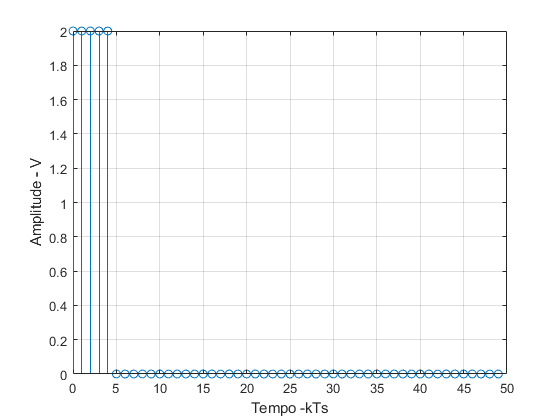

%g = [1 1 1 1];                         % 4 amostras
Ts = 1;                                 %Taxa de amostragem
fs = 1/Ts;                              % Frequencia de amostragem
N = 50;                                 %10 amostras em um periodo
tempo = [0:Ts:(N-1)*Ts];                %variavel tempo
%g = sin(2*pi*tempo/(N*Ts));             % sinal harmonico

g = 1+square((2*pi*tempo/(N*Ts)),10);   %Sinal quadrado

figure()
stem(tempo,g);grid; xlabel("Tempo -kTs"); ylabel("Amplitude - V")

## Calculando a serie discreta de Fourier

Wn = exp(-j*2*pi/N);

for j = 1:N
    n(j) = j-1;
    aux = 0;
    for i = 1:N
        k = i-1;
        aux = aux + g(i)*Wn.^(n(j)*k);         % somatoria para um n fixo - freq
    end
    x(j) = aux/N;                     % determina harmonica
end


## Visualizando o sinal

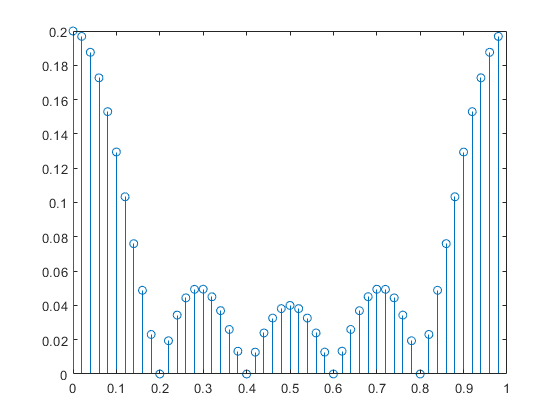

stem(n*fs/N,abs(x))